clc;
clear all;

% Add statistical scripts to path
addpath('/Shared/boeslab/Users/jcgriffis/statistical_scripts/Misc_Code');
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/final_archive_scripts');

% Analysis parameters
min_stroke_age = 0; % Minimum stroke onset age (years)
min_test_age = 0; % Minimum age at PSOM (years)
min_test_interval = 0.5; % Minimum interval between onset and assessment (years)
min_freq = 1; % Minimum lesion frequency
pos_only = 1; % Use only positive model weights for predictions

% Path to adult Lang model
lang_col = "mae_token";
lang_outcome = "worst_lang";    
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Get predicted pediatric scores (lang)
[cfg_lang, beh_csv] =  load_and_format_vips_lesions(lang_outcome);

All subjects with behavioral data have lesion files, N=528 patients will be included


[ui_pred_lang2, ui_pred_lang, vips_pred_lang] = apply_ui_model_vips(lang_col, lang_model_path, cfg_lang, beh_csv, 1, lang_outcome, min_stroke_age, min_test_age, min_test_interval, min_freq, 0, pos_only);

    "Applying model for "    "mae_token"



% Get indices of patients that meet inclusion criteria
inc_ind = find(all([beh_csv.stroke_age >= min_stroke_age, beh_csv.test_age >= min_test_age, beh_csv.yrs2test >= min_test_interval],2));

% Subset dataset and predictions to retain only included patients
beh_csv = beh_csv(inc_ind,:);
ui_pred_lang = ui_pred_lang(inc_ind);
ui_pred_lang2 = ui_pred_lang2(inc_ind);
disp(['N=' num2str(length(inc_ind)) ' included pediatric patients'])

N=469 included pediatric patients


% Define covariates
covs = zscore([beh_csv.lh_vol, beh_csv.rh_vol, beh_csv.stroke_age, beh_csv.yrs2test]);

% Fit ordinal logistic regression models to estimate aOR and compare against base models

% Reverse code and re-code categories (Lang outcome)
Y2 = zeros(length(inc_ind),1);
Y2(beh_csv.(lang_outcome)==0)=3;
Y2(beh_csv.(lang_outcome)==0.5)=2;
Y2(beh_csv.(lang_outcome)==1)=1;
Y2(beh_csv.(lang_outcome)==2)=0;
Y2 = categorical(Y2); 

% Fit base OLR models
mdl2a = fitmnr([covs, covs(:,1).*covs(:,3)], Y2, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'LH Vol*Age'});    

% Add adult predictions (Lang)
mdl2b = fitmnr([covs, covs(:,1).*covs(:,3), zscore(ui_pred_lang)], Y2, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'LH Vol*Age', 'Adult Model'});    

% Add adult predictions (Lang)
mdl2c = fitmnr([covs, covs(:,1).*covs(:,3), zscore(ui_pred_lang), zscore(ui_pred_lang).*covs(:,3)], Y2, 'ModelType', 'ordinal', 'PredictorNames', {'LH Volume', 'RH Volume', 'Age at Stroke', 'Time to Test', 'LH Vol*Age', 'Adult Model', 'Adult Model*Age'}, 'IterationLimit', 1000);    

% Likelihood ratio tests of expanded vs. base models
p_llr_lang(1,1) = 1-chi2cdf(-2*(mdl2a.LogLikelihood-mdl2b.LogLikelihood),1) % Lang

p_llr_lang = single
3.4916e-04

p_llr_lang(2,1) = 1-chi2cdf(-2*(mdl2b.LogLikelihood-mdl2c.LogLikelihood),1) % Lang

p_llr_lang = 2×1 single column vector
    0.0003
    0.5097


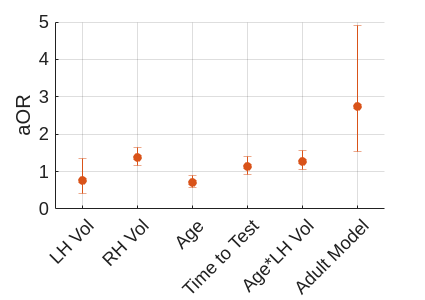


% Get coeffs and CIs
mdl2b_ci = coefCI(mdl2b); mdl2b_ci = exp(mdl2b_ci(4:end,:));
mdl2b_coef = exp(mdl2b.Coefficients.Value(4:end));

% Plot aORs and 95% CIs
clf;
errorbar([1:1:6], mdl2b_coef, mdl2b_coef-mdl2b_ci(:,1), mdl2b_ci(:,2)-mdl2b_coef, 'LineStyle', 'none', 'Marker', '.', 'MarkerSize', 20,'Color', [0.85, 0.325, 0.098]);
xlim([0.5, 6.5]);
ylabel('aOR'); grid on; 
set(gca, 'Xtick', 1:1:7);
set(gca, 'FontSize', 11);
set(gcf, 'color', 'w');
set(gca, 'XtickLabel', {'LH Vol', 'RH Vol', 'Age', 'Time to Test', 'Age*LH Vol', 'Adult Model'});
set(gca, 'XtickLabelRotation', 45);
set(gca, 'FontSize', 14);
set(gcf, 'color', 'w');
set(gcf, 'position', [0, 0, 425, 300]); box off;

cfg.jackknife field is empty; setting to 0 with default settings
Analysis type is other - setting defaults for non-lesion analysis
MATLAB parallel processing functionality detected; parallel processing enabled
Trimming data to retain columns with at least 1 observations greater than or equal to 1
Preallocating CV results
Outer CV repeats:1/5
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:5/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:1/5
Optimal lambda = 0.0058738, fitting model with optimal lambda
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:5/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:1/5
Optimal lambda = 16.533, fitti

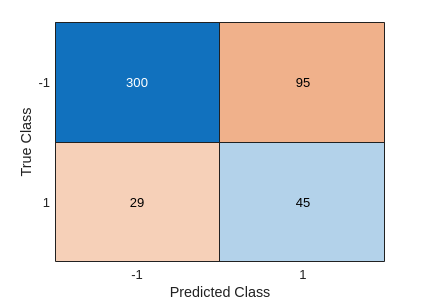

No confounds included, proceeding with main analysis
Running 5 repeats of 5-fold optimization for model hyperparameters
Hyper-parameter optimization iteration:3/5
Hyper-parameter optimization iteration:5/5
Hyper-parameter optimization iteration:2/5
Hyper-parameter optimization iteration:4/5
Hyper-parameter optimization iteration:1/5
Optimal lambda = 0.00018842, fitting model with optimal lambda
Finished running modeling analysis
Time to to complete:0.40167 minutes


% Cross-validation analyses

% Analysis inputs
min_stroke_age = 0;
min_test_age = 0;
min_test_interval = 0.5;
min_freq = 1;
min_freq_stack = 1;
pos_only = 1;
beh_col = 'worst_lang';
model_spec = 'logistic_ridge';

% Path to adult Lang model
lang_col = "mae_token";
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Model types
modalities = {'base_int', 'expanded_pos_int' 'expanded_vips_pos_int'};

% Fit base and expanded models
for i = 1:length(modalities)
    cv_models{i,1} = run_vips_psom_models_cv2(lang_model_path, modalities{i}, model_spec, beh_col, min_stroke_age, min_test_age, min_test_interval,...
        min_freq, min_freq_stack, 0, pos_only);   
    load(fullfile(cv_models{i,1}, 'cv_results.mat'));
    results.(modalities{i}) = cv_results;
    clear cv_results
end

% Plot results
clf;
for j = 1:length(modalities)
    if j == 1
        group = ones(25,1);
    else
        group = [group;ones(25,1).*j];
    end
    plot_results(:,j) = results.(modalities{j}).roc_auc(:);
end
b = boxchart(plot_results(:), 'GroupByColor', group, 'Notch', 'off');
b(2).BoxFaceColor = [0.85, 0.325, 0.098];
b(2).MarkerColor = [0.85, 0.325, 0.098];
b(1).BoxFaceColor = [0,0,0];
b(1).MarkerColor = [0,0,0];
l.IconColumnWidth = 10

l = struct with fields:
    IconColumnWidth: 10


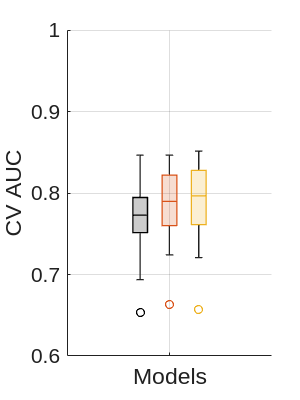

l.Box = "off";
ylim([0.4, 1.05]);
ylabel('CV AUC'); grid on; set(gca, 'XtickLabelRotation', 45);
title(''); set(gca, 'FontSize', 16); set(gcf, 'position', [0, 0, 300, 400]); box off; xlabel('Models'); set(gca, 'XtickLabel', '');
set(gca, 'Ytick', 0.5:0.1:1)
ylim([0.6 1])


% Compare models
plot_results = atan(plot_results);
[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,2)) % base vs. expanded adult

h = 1

p = 8.6531e-06

ci =    -0.0145
   -0.0067


stats = struct with fields:
    tstat: -5.6237
       df: 24
       sd: 0.0094


[h, p, ci, stats] = ttest(plot_results(:,1), plot_results(:,3)) % base vs. expanded pediatric

h = 1

p = 2.8576e-06

ci =    -0.0165
   -0.0081


stats = struct with fields:
    tstat: -6.0717
       df: 24
       sd: 0.0101


[h, p, ci, stats] = ttest(plot_results(:,3), plot_results(:,2)) % expanded adult vs. expanded pediatric

h = 0

p = 0.0887

ci =    -0.0003
    0.0037


stats = struct with fields:
    tstat: 1.7741
       df: 24
       sd: 0.0048
